# Functions

[⇦ Overview](matlab: open("Overview.html"))

Organizing code into functions improves the readability, reusability, and ease of testing your code. A function takes some inputs; runs code in a local scope that might produce side effects like creating a plot; and returns some outputs that will then be available to the rest of your program.

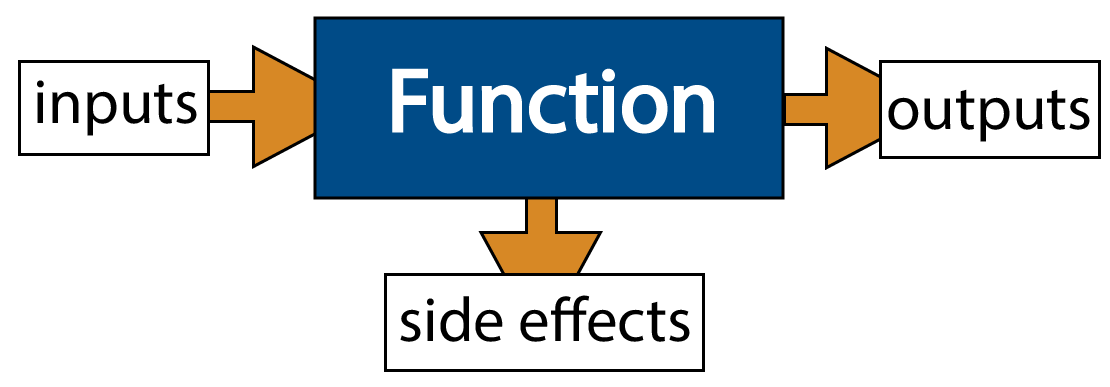

This script addresses built-in functions, refactoring code to create functions, local functions, functions defined in their own files, programmatic scope, the MATLAB path, and how to pass functions as arguments to other functions.

## Programming Languages as Calculators

Programming languages can behave as basic calculators but are far more flexible than your basic four-function calculator. Nearly all programming languages have built-in functions in addition to simple arithmetic, and any specialized mathematical programming language will have far more, including support for complex numbers and built-in constants such as $\pi$. The challenge is tracking and informing the computer about the data type involved in each computation. 

** Exercise 1.**

Evaluate the following expressions using MATLAB as a calculator.

a)` 2.^(1:5)`

`b) sqrt(-9)`

`c) exp(1)`

`d) cos(pi/2)`

`e) cosd(30)`

** Exercise 2.**

Using the documentation, identify the functions used in Exercise 1 by their common mathematical names or notation.

doc ^
doc sqrt




a) C = A^B is 

b) B = sqrt(X) is

c) Y = exp(X) is 

d) Y = cos(X) is 

e) Y = cosd(X) is 

**Solution:**

a) 

b) 

c) 

d)

e) 

 **Reflect**. 

- What are the implications of having both `cos()` and `cosd()`? 

- Are there advantages to using `exp()` and `sqrt()` over their standard mathematical notations? Why or why not?

### Composition of Functions

As with mathematical functions, programmatic functions can be composed whenever the output type of the inner function is the input type of the argument for the outer function. 

(cosd(30))^2
x = 1:100;
plot(x,sqrt(x))

As in mathematics, there are limitations on the ability to compose functions in a programming language. Try running the following code after pasting it into the code box below. What do you expect to happen?

### Assignment Operator

Every programming language has some way of assigning expressions to names that can be used later in the code in place of that expression. Just as in algebra, you can use a single symbol to represent a function, $y = 3x^2-7x+1$, that can then be used inside other functions:

$f = \frac{e^{y/3}}{-0.6y^2+\cos(y)} = \frac{e^{x^2-\frac{7}{2}x+\frac{1}{3}}}{-5.4x^4+25.2x^3-33x^2+8.4x-.6+\cos(3x^2-7x+1)}$.

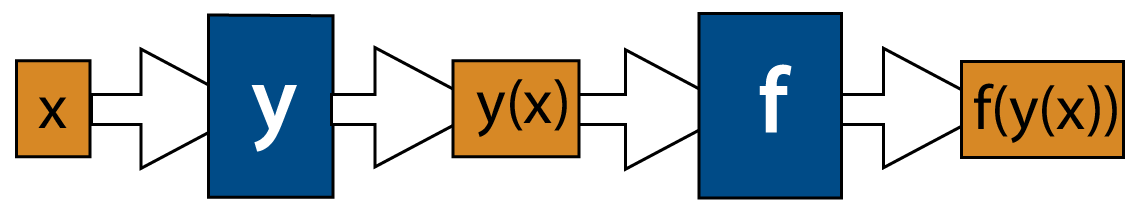

Such assignment allows the programmer to build up complex operations step-by-step. In MATLAB, a variable is assigned to a value using the symbol `=`. 

** Exercise 3.**

Calculate the value of $f$ if $x=0$, $x=4.3$, $x=2.18045$ and $x=-\frac{\sqrt{\pi}}{2}$. 

## Using Refactor

A traditional function to code in any new programming language is to print the phrase "Hello, world!". Simply printing this phrase is easy:

disp("Hello, world!")

How could we create a script that would greet a user by name? First, define a variable called `name`.

name = "Sara"

Then use this name to display the string you want:

disp("Hello, " + name + "!")

Select the "Hello, name!" code, and on the **Live Editor** tab, in the **Code** section, click   **Refactor** and select **Convert from Local Function** from the available options. This will cut and paste this code to the end of the script as a function called `untitled`. Fix the name to be more descriptive, such as `helloWorld`, and then scroll back here. What happened to your code? Does it still work the way you expect if you run it?

### Inputs, Outputs & Side Effects

The `helloWorld` function has one input, `name`, one side effect, printing a string to the display, and no outputs.

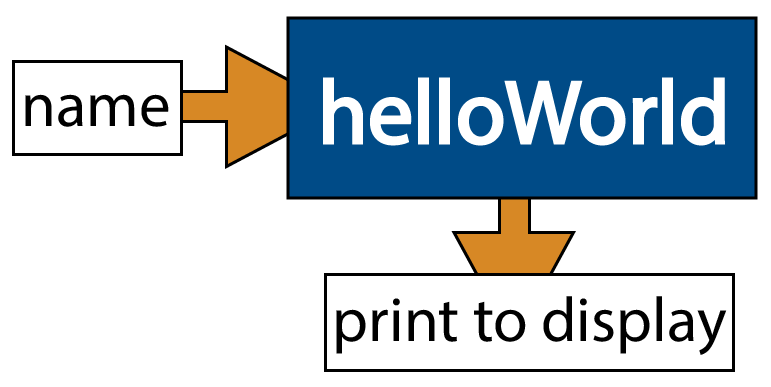

 For each function you write, you must carefully document what values it requires to run. Pass the required values in as a list of arguments. You also need to consider what values you want to have after running the script and define those to be the output values for your function. Finally, you want to decide what side effects or impacts running the function will have on other parts of the system. 

## Local Functions

If there is a set of operations that you know will repeat, or that form a logical unit of code, you can define a local function, as with `helloWorld`. For example, to define a function named `functionName` with three input values, `arg1`, `arg2`, and `arg3`, and two output values, `out1` and `out2`, the MATLAB syntax is: 

Other programming languages use different syntax, but they all have some way of identifying input values, output values, a name for the function, and what the program should do when the function is called. 

Within a live script, local functions must be defined at the end of the file and called anywhere throughout the live script.

  **Try**. 

- Go to the end of this file and define a function called `quadFormula` that implements the quadratic root-finding formula. Given a quadratic equation $ax^2+bx+c = 0$, the solutions are:

$x_+ = \frac{-b + \sqrt{b^2-4ac}}{2a}$ and $x_- = \frac{-b-\sqrt{b^2-4ac}}{2a}$

That means your function takes three arguments, `a`, `b`, and `c`, and returns two values, `xPlus` and `xMinus.` 

          2. Can you simplify the code for `quadFormula` by defining another function called `discriminant` that only calculates the value of $\sqrt{b^2-4ac}$? Notice that functions can call other functions, just as you can call functions from the command line or in a script. This is the programmatic version of function composition. 

Once you have defined a function, you can call that function using the name you gave it just as you would any other function within the language. 

% Uncomment and run this code after you have defined quad
% With a = 1, b = 2, c = -3, the correct values are 
% xPlus = 1 and xMinus = -3 
a = 1;
b = 2; 
c = -3; 

% [xPlus,xMinus] = quad(a,b,c)

 **Reflect**. 

- How can you check if you have implemented your function correctly? 

- What happens if you pass in incorrect values, such as the strings `"a"`, `"b"`, and `"c"` rather than numerical values for the coefficients? What happens if you pass numerical values directly, e.g., `quad(1,2,-3)`?

- What happens if you call the function with different names for the output values? Perhaps you use `r1` and `r2,` or `x1` and `x2,` instead of `xPlus` and `xMinus`?

- What happens if you call `quad` with only one output variable defined? Or no output variables at all?

- What happens if you call `quad` with three output variables defined?

- Does `quad` work in both this script and the Command Window?

% Additional test equations: x^2-9 = 0, 6x^2+11x-10 = 0, and x^2+x+1=0

## Function Files

In other cases, we may want to define [functions](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html) that will be accessible from several different scripts or separate the functions into different files and folders to create nicely organized code. You can create functions in MATLAB as either live script `(*.mlx)` or M-files `(*.m).` 

  **Try**. 

- Create a new live script on the **Live Editor **tab of the toolstrip by selecting  **New **and then  **Live Script**. Alternately, you can select the tab marked + at the top of the Live Editor window. 

- Cut and paste the function (and subfunctions, if they exist) into the new `.mlx` file. Save the new file with the same name as the function, in this case, `quad.m`.

- Use your new function here, and test that it now works in the Command Window.

 **Reflect**. 

- When does defining a function as part of a script make sense? 

- When might you want to use inline commands? Or functions defined in separate files? 

## Scope

Where can you use `quad`? Does it work inside this live script? On the command line in the Command Window? From a different live script?  The answers to these questions are related to the concept of the *scope* of a function or variable. Computers must be told where to find the commands or data you want them to use.

### MATLAB Path

In MATLAB, the scope of a function is related to the idea of the [MATLAB path](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html), which is the set of files, in order, that should be searched to determine if there is a function with a given name defined. You can programmatically change the [MATLAB search path](https://www.mathworks.com/help/matlab/search-path.html) using commands in a script, function, or the Command Window. You can also use the context menus of the Graphical User Interface by right-clicking on folders in the Current Folder panel. If you have implemented a function, but it is not on your search path, then MATLAB will not find it, and you will likely get an error when you try to use it. 

 This does mean that defining a local function of your own can overload a function name so that your version of a function will be called rather than the standard MATLAB version. This is why you may want to check the MATLAB documentation to see if there is a function you want to use that has the same name and arguments as a function you want to define. If you want to know which implementation of a function is found first, you can use the command `which`.

which quad
which -all quad

  **Try**. Can you check the documentation to determine what the MATLAB `quad` function does? What command does the documentation suggest that you use instead?

 **Reflect**. 

- What do you think it means for functions to be `Shadowed` in MATLAB? 

- How does MATLAB choose which version of `quad` to use when there is more than one on the MATLAB Path?

- Is it possible that you could call a different `quad` than you meant to call without realizing it? Why or Why not?

- Why might you want to restrict the scope of a variable or a function?

  **Try**.

Move the `quad.mlx` file into the `HelperFunctions` folder. Try running `quad.mlx` here and in the Command Window. Then right-click `HelperFunctions` and select **Remove from path > Selected folders**. Try running `quad.mlx` again. Right-click `HelperFunctions` and select **Add to path > Selected folders **before you continue with this script. 

% Find the roots of 6x^2+11x-10 = 0


## Scope

There are limits to what a program can read, write, or execute. These limits are called the scope. In MATLAB, the workspace tracks the variables currently in scope for your program to read and write. The current workspace is displayed in the Workspace browser. For each variable, the [Workspace browser](https://www.mathworks.com/help/matlab/ref/workspace.html) displays an icon indicating the broad type, the name, and either the scalar value directly or the size and class information linking to the Variables editor. 

When executing a function call, a new workspace is created that is locally scoped, so the variables defined are only accessible inside that function call. This is why you must pass arguments and return values explicitly as part of your function call. You can access the workspace inside a function using tools for debugging to step inside the function call. 

Some programming languages allow the definition of variables together with a particular scope, including the potential for globally scoped values that can be read or written from anywhere. You must be especially careful with function and variable naming in the context of globally scoped  so you don't accidentally change things you did not mean to change.

  **Try.**

- Clear all the values in the current workspace to make it easy to see what you are working with by using

either in the script or the command window. 

          2. Set up several new variables. After running this code, which variables will be in your workspace?

Tom = randi(20,1);
[m,idx] = min(Tom); 
str = "A cat";
for k = 1:3
    sub = " and a kitten";
    str = str + sub;
end
 


          3. Clear your workspace again. Use Refactor to turn the `for` loop into a function that takes a string as input and returns `str` as output. Then rerun this section. What variables are in the workspace now?

## Function Handles: Passing functions as arguments

Sometimes you may want to pass a function as one of the input arguments to a function. This requires a new data type: a [function handle](https://www.mathworks.com/help/matlab/ref/function_handle.html). It is possible to create a function handle from a function using the symbol `@`.

will be a function handle to the function `functionName`. 

### Anonymous functions

[Anonymous functions](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) do not have names and are defined inline by identifying their arguments and the rule for computing the single output value. An anonymous function has the data type `function_handle`. Anonymous functions can be used to define all sorts of functions, including mathematical functions:

tsc = @(x,shift) sin(1./x) + shift
xValues = linspace(0,1,1000);
plot(xValues(2:end),tsc(xValues(2:end),-1))
title("A plot of the shifted topologist's sine curve")

Anonymous functions can include other anonymous functions. To express the mathematical function


$$g(c) = \int_0^{\pi}\sin(cx)\;dx,$$


as an anonymous function:

g = @(c) (integral(@(x) sin(c.*x),0,pi));

Then we can evaluate this function with the same notation we use in mathematics:

g(0.3)

One common use case for anonymous functions is for calling functions where one input type is a function handle. Consider the function `showTaylor`.

help showTaylor.mlx

Now try running `showTaylor`. Does it behave as you expect, given the documentation?

deg = 1:20;
showTaylor(@(x) sin(x).*exp(x),deg,[-2*pi 2*pi],0.5)

** Exercise 4. **

- Create a function called `buildWord` that takes a length and returns a string of letters of that length. You are not required to ensure that the word means anything in any known language. Make sure that `buildWord` is on your MATLAB path.

- Create a function called `markMidpoint` that takes the coordinates of the endpoints of a line segment in the plane and plots (using `hold on` and `hold off`, so it can be added to an existing plot) a filled yellow circle at the midpoint of the line segment. It should also return the coordinates of the midpoint as a vector. Make sure that `markMidpoint` is on your MATLAB path.

% Test your code here by uncommenting the appropriate command
% checkBuildWord(@buildWord)
% checkMarkMidpoint(@markMidpoint)

** Exercise 5.**

 There are also built-in functions that require function handles as arguments. This is especially common for functions intended to operate on mathematical functions. Use the function [`fzero`](https://www.mathworks.com/help/matlab/ref/fzero.html) to solve the equation $\cos(x) = xe^{-\sin(x)}$.

**Hint:** You might want to start by graphing the function to generate a reasonable guess.

**Hint 2:** Since `fzero` locates the zeros of a function, what is the function $f(x)=0$ that solves the equation $\cos(x)=xe^{-\sin(x)}$?

% Fix this code so that mySoln contains your solution to Exercise 5
mySoln = 0;


checkExercise5(mySoln);

## Further Explorations

You can take advantage of overloading functions by defining different versions of a function that accept different sets of arguments using [`varargin`](https://www.mathworks.com/help/matlab/ref/varargin.html) or different sets of output using [`varargout`](https://www.mathworks.com/help/matlab/ref/varargout.html).

To dive further into these topics, consider working through the [Creating Flexible Functions](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr#module=5) module in the self-paced [MATLAB Programming Techniques](https://matlabacademy.mathworks.com/details/matlab-programming-techniques/mlpr) course. 

[⇦ Return to the navigation page](matlab: open("Overview.html"))

## Local Functions

Return to the discussion of implementing the quadratic equation solver.

%#ok<*DQUAD> 

% Write your quad function here
 

